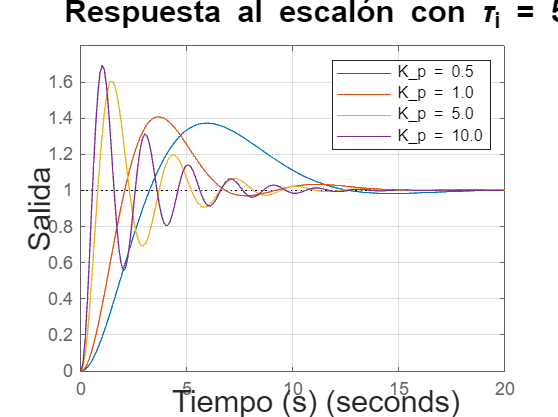

% PI_analisis_completo.m
close all;
clear;
clc;

% Parámetros del sistema
K = 1;
p = 1;
t = 0:0.1:20;

%% =============================
%% 1. Respuesta al escalón
%% =============================

% --- Gráfica 1: tau_i fijo, Kp variable ---
taui_fixed = 5;
Kp_vals = [0.5, 1, 5, 10];

fig1 = figure('Units', 'centimeters', 'Position', [2, 2, 20, 15]);
hold on;
for i = 1:length(Kp_vals)
    Kp = Kp_vals(i);
    num_L = Kp * K * [taui_fixed, 1];
    den_L = conv([taui_fixed, 0], [1, p, 0]);  % taui*s * s*(s+p)
    L = tf(num_L, den_L);
    sys = feedback(L, 1);
    step(sys, t);
end
title(['Respuesta al escalón con \tau_i = ' num2str(taui_fixed)], 'FontSize', 17);
xlabel('Tiempo (s)', 'FontSize', 17);
ylabel('Salida', 'FontSize', 17);
legend(arrayfun(@(k) sprintf('K_p = %.1f', k), Kp_vals, 'UniformOutput', false));
grid on;
print(fig1, 'PI_salidaKpvar', '-dpdf', '-r300');

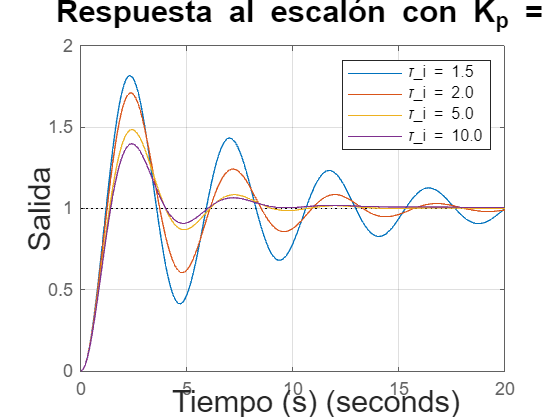


% --- Gráfica 2: Kp fijo, tau_i variable ---
Kp_fixed = 2;
taui_vals = [1.5, 2, 5, 10];

fig2 = figure('Units', 'centimeters', 'Position', [2, 2, 20, 15]);
hold on;
for i = 1:length(taui_vals)
    taui = taui_vals(i);
    num_L = Kp_fixed * K * [taui, 1];
    den_L = conv([taui, 0], [1, p, 0]);
    L = tf(num_L, den_L);
    sys = feedback(L, 1);
    step(sys, t);
end
title(['Respuesta al escalón con K_p = ' num2str(Kp_fixed)], 'FontSize', 17);
xlabel('Tiempo (s)', 'FontSize', 17);
ylabel('Salida', 'FontSize', 17);
legend(arrayfun(@(t) sprintf('\\tau_i = %.1f', t), taui_vals, 'UniformOutput', false));
grid on;
print(fig2, 'PI_salidaTauivar', '-dpdf', '-r300');

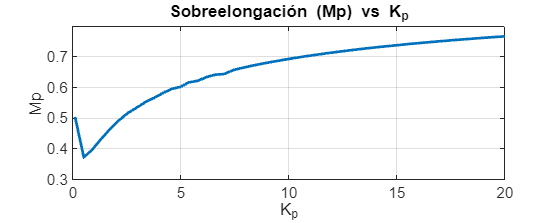


%% =============================
%% 2. Análisis del transitorio vs Kp
%% =============================

% Barrido de Kp y cálculo de métricas
Kp_vals = linspace(0.1, 20, 50);  % 50 valores entre 0.1 y 20
Mp = zeros(size(Kp_vals));
Tp = zeros(size(Kp_vals));
Tr = zeros(size(Kp_vals));
Ts = zeros(size(Kp_vals));

for i = 1:length(Kp_vals)
    Kp = Kp_vals(i);
    num_L = Kp * K * [taui_fixed, 1];
    den_L = conv([taui_fixed, 0], [1, p, 0]);
    L = tf(num_L, den_L);
    sys = feedback(L, 1);
    info = stepinfo(sys, 'RiseTimeLimits', [0.1 0.9]);
    Mp(i) = info.Peak-1;
    Tp(i) = info.PeakTime;
    Tr(i) = info.RiseTime;
    Ts(i) = info.SettlingTime;
end

% Gráficas de las métricas
figure('Units', 'centimeters', 'Position', [2, 2, 20, 8]);
plot(Kp_vals, Mp, 'LineWidth', 1.5);
xlabel('K_p'); ylabel('Mp');
title('Sobreelongación (Mp) vs K_p'); grid on;

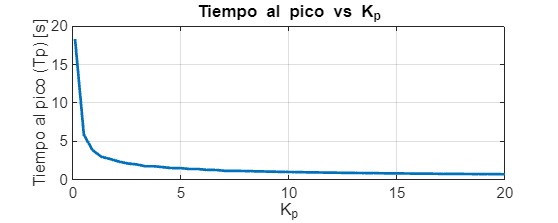


figure('Units', 'centimeters', 'Position', [2, 2, 20, 8]);
plot(Kp_vals, Tp, 'LineWidth', 1.5);
xlabel('K_p'); ylabel('Tiempo al pico (Tp) [s]');
title('Tiempo al pico vs K_p'); grid on;

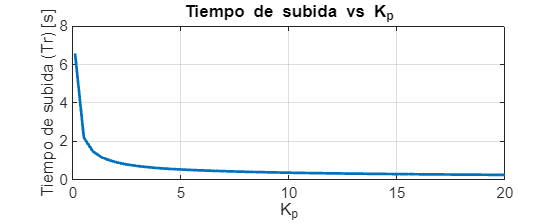


figure('Units', 'centimeters', 'Position', [2, 2, 20, 8]);
plot(Kp_vals, Tr, 'LineWidth', 1.5);
xlabel('K_p'); ylabel('Tiempo de subida (Tr) [s]');
title('Tiempo de subida vs K_p'); grid on;

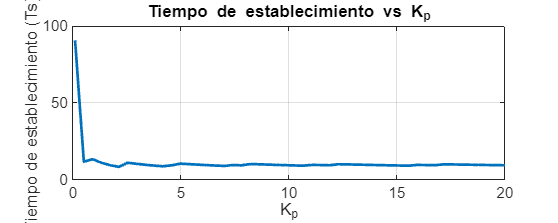


figure('Units', 'centimeters', 'Position', [2, 2, 20, 8]);
plot(Kp_vals, Ts, 'LineWidth', 1.5);
xlabel('K_p'); ylabel('Tiempo de establecimiento (Ts) [s]');
title('Tiempo de establecimiento vs K_p'); grid on;


%% =============================
%% 3. Análisis del transitorio vs tau_i
%% =============================

% Fijamos Kp y barrido de tau_i
Kp_fixed = 1;
taui_vals = linspace(0.5, 10, 50);  % 50 valores entre 0.5 y 10

Mp_tau = zeros(size(taui_vals));
Tp_tau = zeros(size(taui_vals));
Tr_tau = zeros(size(taui_vals));
Ts_tau = zeros(size(taui_vals));

for i = 1:length(taui_vals)
    taui = taui_vals(i);
    num_L = Kp_fixed * K * [taui, 1];
    den_L = conv([taui, 0], [1, p, 0]);
    L = tf(num_L, den_L);
    sys = feedback(L, 1);
    info = stepinfo(sys, 'RiseTimeLimits', [0.1 0.9]);
    Mp_tau(i) = info.Peak - 1;
    Tp_tau(i) = info.PeakTime;
    Tr_tau(i) = info.RiseTime;
    Ts_tau(i) = info.SettlingTime;
end

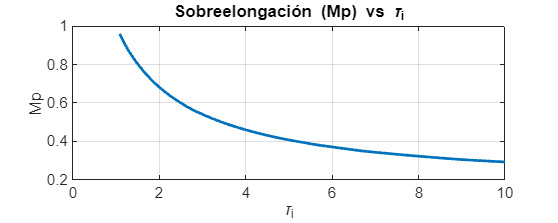


% Gráficas
figure('Units', 'centimeters', 'Position', [2, 2, 20, 8]);
plot(taui_vals, Mp_tau, 'LineWidth', 1.5);
xlabel('\tau_i'); ylabel('Mp');
title('Sobreelongación (Mp) vs \tau_i'); grid on;

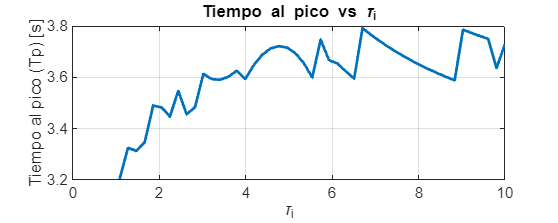


figure('Units', 'centimeters', 'Position', [2, 2, 20, 8]);
plot(taui_vals, Tp_tau, 'LineWidth', 1.5);
xlabel('\tau_i'); ylabel('Tiempo al pico (Tp) [s]');
title('Tiempo al pico vs \tau_i'); grid on;

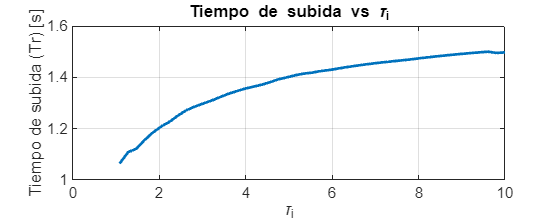


figure('Units', 'centimeters', 'Position', [2, 2, 20, 8]);
plot(taui_vals, Tr_tau, 'LineWidth', 1.5);
xlabel('\tau_i'); ylabel('Tiempo de subida (Tr) [s]');
title('Tiempo de subida vs \tau_i'); grid on;

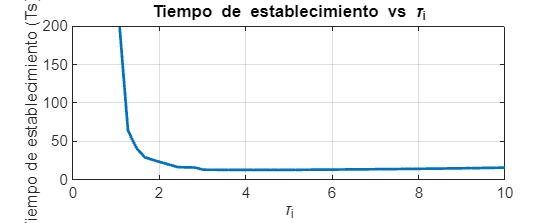


figure('Units', 'centimeters', 'Position', [2, 2, 20, 8]);
plot(taui_vals, Ts_tau, 'LineWidth', 1.5);
xlabel('\tau_i'); ylabel('Tiempo de establecimiento (Ts) [s]');
title('Tiempo de establecimiento vs \tau_i'); grid on;